# Puma 'FKINE' and plot functions

Author: Javier Cabrera & Júlia Gasull

MatlaDrive Link: [https://drive.matlab.com/sharing/49eb5fa6-0641-425c-a130-9cf41b2e1058](https://drive.matlab.com/sharing/49eb5fa6-0641-425c-a130-9cf41b2e1058)

Deliver:

- Assemble the  Robot  using the links of the puma, based on the STL parts given.

- Let us try to animate some links

## Model to be followed

Use DH parameters from Standard convection of Puma560

Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


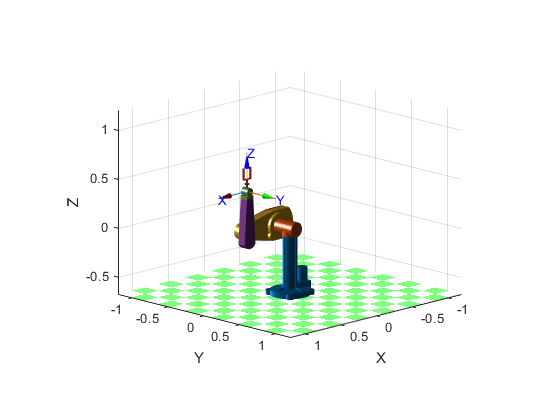

mdl_puma560
p560.plot3d([0 0 0 0 0 0])

p560

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


## Puma Links

### Initial variables

REF = [];
V = [];
F = [];
color = [[0 0 1]; [1 0 0]; [1 1 0]; [1 0 1]; [0 1 0]; [0 0 1]; [1 0 0]];

### Link 0

figure
[V(1), F(1), N, name]=stlRead('link0.stl');

Unable to perform assignment because the indices on the left side are not compatible with the size of the right side.

FVsPlot(F(1),V(1),color(1,:))
axis equal
view(130, 10)

### Link 1

%figure
hold on
[V, F, N,name]=stlRead('link1.stl');
V = V*rotx(-pi/2);
REF = [REF; [0 0 0]];
FVsPlot(F,V,color(2,:))
axis equal
view(130, 10)

### Link 2

[V,F, N,name]=stlRead('link2.stl');
V = V*roty(pi/2)*rotx(-pi/2)*rotz(-pi/2)+[0.4318 0 0];
REF = [REF; [0 -0.1845 0]];
FVsPlot(F,V,color(3,:))
axis equal
view(130, 10)

### Link 3

[V,F, N,name]=stlRead('link3.stl');
V = V+[0.4, -0.14, 0];
REF = [REF; [0.4, -0.1845, 0]];
FVsPlot(F,V,color(4,:))
axis equal
view(130, 10)

### Link 4

[V,F, N,name]=stlRead('link4.stl');
V = V*rotx(-pi/2)+[0.4 -0.14 0.4318];
REF = [REF; [0.4 -0.14 0.4318]];
FVsPlot(F,V,color(5,:))
axis equal
view(130, 10)

### Link 5

[V,F, N,name]=stlRead('link5.stl');
V = V+[0.4 -0.14 0.4318];
REF = [REF; [0.4 -0.14 0.4318]];
FVsPlot(F,V,color(6,:))
axis equal
view(130, 10)

### Link 6

[V,F, N,name]=stlRead('link6.stl');
V = V+[0.4 -0.14 0.4318];
REF = [REF; [0.4 -0.14 0.4318+0.043]];
FVsPlot(F,V,color(7,:))
axis equal
view(130, 10)

## Plot function

function T_b_a=FVsPlot(F,V,color)
patch('Faces',F,'Vertices',V,'FaceColor',color, ...
         'FaceAlpha',0.8,...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('dull');

grid on
xlabel 'X [mm]'
ylabel 'Y [mm]'
zlabel 'Z [mm]'
end


## Movement function

function T_algo=moveq1()


end